# 1CWK50 submission

Full instructions on how to submit this live script are available in the assignment specification on Moodle ("How to submit your work" section). Make sure you read them carefully, and that you test your final submission thoroughly before uploading it to Moodle. No additional files can be accepted after the deadline has passed.

## 1. Dataset preparation (20%)

% check the dataset is present:
if ~exist('moons.csv', 'file')
    error('You need to download moons.csv from Moodle and place it into the same directory as this live script');
end

rng(0); % re-seed the random number for reproducible results

% add your code on the lines below:

data = readcell('moons.csv'); %reads the data cells of the file

data(1:1:10, 1:1:end) %reads through the data 1 at a time for the first 10 values going downwards

ans = 10×3 cell array
    {'Feature 1'}    {'Feature 2'}    {'Label'  }
    {[   0.1567]}    {[   1.3182]}    {'Class A'}
    {[  -0.9705]}    {[   0.6211]}    {'Class A'}
    {[  -0.9086]}    {[   0.1598]}    {'Class A'}
    {[   0.7076]}    {[   0.2604]}    {'Class A'}
    {[  -1.2325]}    {[   0.9279]}    {'Class A'}
    {[  -0.6282]}    {[   0.8368]}    {'Class A'}
    {[   0.6124]}    {[   0.2656]}    {'Class A'}
    {[  -0.7009]}    {[  -0.0706]}    {'Class A'}
    {[   1.2655]}    {[   1.3637]}    {'Class A'}



observed = data(2:end,:);

observed_shuffled = observed(randperm(size(observed,1)), :); %shuffles data

nTest = round(0.4 * size(observed_shuffled,1)) %uses 40% of shuffled values as testing data

nTest = 60


observed_test = observed_shuffled(1:1:nTest, :);
observed_train = observed_shuffled(nTest+1:1:end, :);

labels = 3; %number of labels

test_labels = categorical(observed_test(:, labels)); %number of labels being observed (feature 1, feature 2, label)
test_examples = cell2mat(observed_test(:, 1:end~=labels)); %reads through each of the columns of the labels given

size(test_examples) %shows size of test examples

ans =     60     2


size(test_labels) %shows size of test labels

ans =     60     1



train_labels = categorical(observed_train(:, labels));
train_examples = cell2mat(observed_train(:, 1:end~=labels));

size(train_examples) %shows size of training examples

ans =     90     2


size(train_labels) %shows size of training labels

ans =     90     1


## 2. Feature space visualisation (20%)

rng(0); % re-seed the random number for reproducible results

% add your code on the lines below:

test_nb = fitcnb(train_examples, train_labels) %classifies training examples and training labels using the Naive Bayes classification

test_nb =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [Class A    Class B]
            ScoreTransform: 'none'
           NumObservations: 90
         DistributionNames: {'normal'  'normal'}
    DistributionParameters: {2×2 cell}


  Properties, Methods



nbpredictions = test_nb.predict(test_examples); %generates a prediction

predicted_nb = sum(nbpredictions == test_labels) / length(test_labels) %calculates decimal prediction based on predicted labels compared to tested labels

predicted_nb = 0.8500

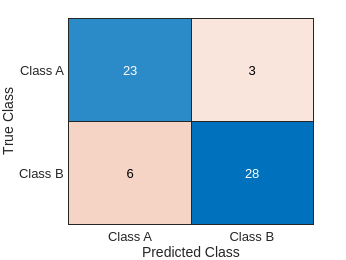


confusionchart(test_labels, nbpredictions) %generates chart that shows the predicted labels in a chart to see how many of each feature were predicted

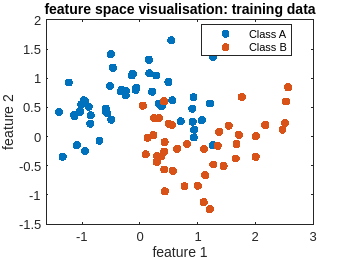



figure; % open a new figure window, ready for plotting

gscatter(test_nb.X(:,1),test_nb.X(:,2),test_nb.Y) %creates a scatter graph using the 2 features from the testing examples
xlabel("feature 1");
ylabel("feature 2");
title("feature space visualisation: training data");

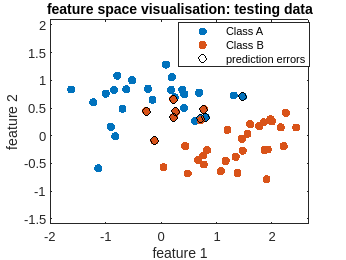



figure; % open a new figure window, ready for plotting for misclassified predictions

% add your code on the lines below:
gscatter(test_examples(:,1),test_examples(:,2),test_labels)
xlabel("feature 1");
ylabel("feature 2");
title("feature space visualisation: testing data");
axis('equal');
hold('on'); %allows us to draw on the graph that is currently being shown/created
misclassified = (nbpredictions ~= test_labels); %checks which predictions are not equal to the test labels
scatter(test_examples(misclassified,1),test_examples(misclassified,2),'ok', 'DisplayName', 'prediction errors') %displays prediction errors as circles around some of the graph values

## 3. Abstraction visualisations (20%)

rng(0); % re-seed the random number for reproducible results

% add your code on the lines below:

test_knn = fitcknn(train_examples, train_labels, 'NumNeighbors', 1) %training knn prediction with 1 nearest neighbour

test_knn =   ClassificationKNN
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Class A    Class B]
           ScoreTransform: 'none'
          NumObservations: 90
                 Distance: 'euclidean'
             NumNeighbors: 1


  Properties, Methods



knnpredictions = test_knn.predict(test_examples); %prediction generated from testing examples

predicted_knn = sum(knnpredictions == test_labels) / length(test_labels)

predicted_knn = 0.8833

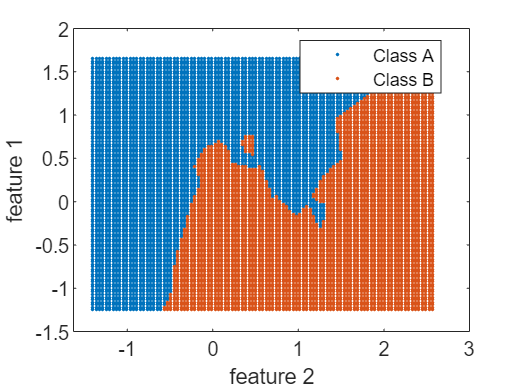


figure;
visualise_abstraction(test_knn) %calls my visualise abstraction class function to generate a graph to show the abstraction
xlabel("feature 2");
ylabel("feature 1");


test_knn2 = fitcknn(train_examples, train_labels, 'NumNeighbors', 5) %training knn prediction with 5 nearest neighbours

test_knn2 =   ClassificationKNN
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Class A    Class B]
           ScoreTransform: 'none'
          NumObservations: 90
                 Distance: 'euclidean'
             NumNeighbors: 5


  Properties, Methods



knnpredictions2 = test_knn2.predict(test_examples);

predicted_knn2 = sum(knnpredictions2 == test_labels) / length(test_labels)

predicted_knn2 = 0.9000

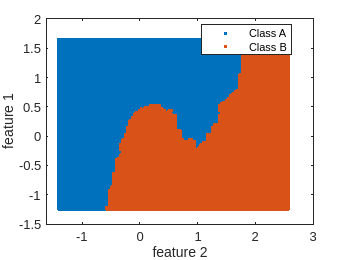


figure;
visualise_abstraction(test_knn2)
xlabel("feature 2");
ylabel("feature 1");


%----------------------------------------------------------------------------------------------------------------------

test_dt = fitctree(train_examples, train_labels, 'MergeLeaves', 'off', 'Prune', 'off', 'MinParentSize', 10); %training dt prediction with minimum 10 parents

dtpredictions = test_dt.predict(test_examples); %prediction generated from testing examples

predicted_dt = sum(dtpredictions == test_labels) / length(test_labels)

predicted_dt = 0.9333

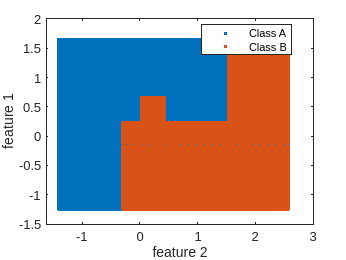


figure;
visualise_abstraction(test_dt)
xlabel("feature 2");
ylabel("feature 1");




test_dt2 = fitctree(train_examples, train_labels, 'MergeLeaves', 'off', 'Prune', 'off', 'MinParentSize', 1); %training dt prediction with minimum 1 parents

dtpredictions2 = test_dt2.predict(test_examples);

predicted_dt2 = sum(dtpredictions2 == test_labels) / length(test_labels)

predicted_dt2 = 0.9333

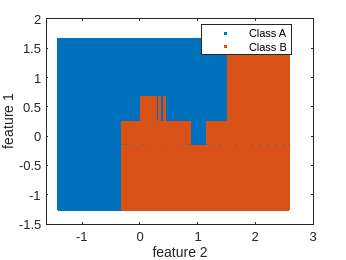


figure;
visualise_abstraction(test_dt2)
xlabel("feature 2");
ylabel("feature 1");

## 4. Classifier re-implementations (20%)

rng(0); % re-seed the random number for reproducible results

% add your code on the lines below:

mytest_knn = my_ClassificationKNN(train_examples, train_labels, 'NumNeighbors', 1) %training knn prediction with 1 nearest neighbour

mytest_knn =   my_ClassificationKNN with properties:

               X: [90×2 double]
               Y: [90×1 categorical]
    NumNeighbors: 'NumNeighbors'
         Verbose: 1



myknnpredictions = mytest_knn.predict(test_examples); %prediction generated from testing examples

mypredicted_knn = sum(myknnpredictions == test_labels) / length(test_labels)

mypredicted_knn = 0.7500

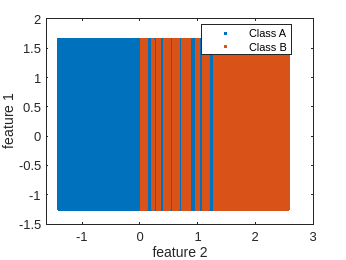


figure;
visualise_abstraction(mytest_knn) %calls my visualise abstraction class function to generate a graph to show the abstraction
xlabel("feature 2");
ylabel("feature 1");


mytest_knn2 = my_ClassificationKNN(train_examples, train_labels, 'NumNeighbors', 5) %training knn prediction with 5 nearest neighbours

mytest_knn2 =   my_ClassificationKNN with properties:

               X: [90×2 double]
               Y: [90×1 categorical]
    NumNeighbors: 'NumNeighbors'
         Verbose: 5



myknnpredictions2 = mytest_knn2.predict(test_examples);

mypredicted_knn2 = sum(myknnpredictions2 == test_labels) / length(test_labels)

mypredicted_knn2 = 0.7500


figure;
visualise_abstraction(mytest_knn2)
xlabel("feature 2");
ylabel("feature 1");


%----------------------------------------------------------------------------------------------------------------------

% mytest_dt = my_ClassificationTree(train_examples, train_labels, 'MinParentSize', 10); %training dt prediction with minimum 10 parents
% 
% mydtpredictions = mytest_dt.predict(test_examples); %prediction generated from testing examples
% 
% mypredicted_dt = sum(mydtpredictions == test_labels) / length(test_labels)
% 
% figure;
% visualise_abstraction(mytest_dt)
% xlabel("feature 2");
% ylabel("feature 1");
% 
% 
% 
% mytest_dt2 = my_ClassificationTree(train_examples, train_labels,'MinParentSize', 1); %training dt prediction with minimum 1 parents
% 
% mydtpredictions2 = mytest_dt2.predict(test_examples);
% 
% mypredicted_dt2 = sum(mydtpredictions2 == test_labels) / length(test_labels)
% 
% figure;
% visualise_abstraction(test_dt2)
% xlabel("feature 2");
% ylabel("feature 1");

## 5. Extension to ensembles (20%)

rng(0); % re-seed the random number for reproducible results

% add your code on the lines below:

en_test_knn = my_ClassificationKNN(train_examples, train_labels, 'NumNeighbors', 1) %training knn prediction with 1 nearest neighbour

en_test_knn =   my_ClassificationKNN with properties:

               X: [90×2 double]
               Y: [90×1 categorical]
    NumNeighbors: 'NumNeighbors'
         Verbose: 1



enknnpredictions = en_test_knn.predict(test_examples); %prediction generated from testing examples

predicted_knn = sum(enknnpredictions == test_labels) / length(test_labels)

predicted_knn = 0.7500


[predicted_knn, score_knn] = en_test_knn.predict(test_examples);

Error using my_ClassificationKNN/predict
Too many output arguments.




en_test_nb = my_ClassificationNaiveBayes(train_examples, train_labels) %classifies training examples and training labels using the Naive Bayes classification

ennbpredictions = en_test_nb.predict(test_examples); %generates a prediction

predicted_nb = sum(ennbpredictions == test_labels) / length(test_labels) %calculates decimal prediction based on predicted labels compared to tested labels

[predictions_nb, score_nb] = en_test_nb.predict(test_examples);


en_test_dt = my_ClassificationTree(train_examples, train_labels, 'MinParentSize', 10); %training dt prediction with minimum 10 parents

endtpredictions = en_test_dt.predict(test_examples); %prediction generated from testing examples

predicted_dt = sum(endtpredictions == test_labels) / length(test_labels)

[predictions_dt, score_dt] = en_test_dt.predict(test_examples);


enscore1 = (score_knn + score_nb) ./2 %calculates an average for knn and nb scores

[~, ind] = max(enscore1') %formats the scores so they can be used in the correct array format
predictions_en = en_test_knn.ClassNames(ind)

p_en = sum(predictions_en == test_labels) / length(test_labels)

scores_nb
scores_knn
figure;
visualise_abstraction(enscore1); %visualises scores
xlabel('feature 1');
ylabel('feature 2');
en_test_knn.ClassNames
legend(en_test_knn.ClassNames);


enscore2 = (score_knn + score_nb + score_dt) ./3 %calculates average for previous scores and dt

[~, ind] = max(enscore2')
predictions_en2 = en_test_dt.ClassNames(ind)

p_en2 = sum(predictions_en2 == test_labels) / length(test_labels)

enscore1
scores_dt
figure;
visualise_abstraction(enscore2);
xlabel('feature 1');
ylabel('feature 2');
en_test_dt.ClassNames
legend(en_test_dt.ClassNames);